# Color differences of 24 patches in four different modes of Spyder X

## Input -- test target

load('colorchecker_test_result_rift.mat','spd_ol490_24','spd_disp_24')

colorchecker = [
    115 82  68;
    194 150 130;
    98  122 157;
    87  108 67;
    133 128 177;
    103 189 170;

    214 126 44;
    80  91  166;
    193 90  99;
    94  60  108;
    157 188 64;
    224 163 46;

    56  61  150;
    70  148 73;
    175 54  60;
    231 199 31;
    187 86  149;
    8   133 161;

    243 243 242;
    200 200 200;
    160 160 160;
    122 122 121;
    85  85  85;
    52  52  52
    ];

## Generate the plots

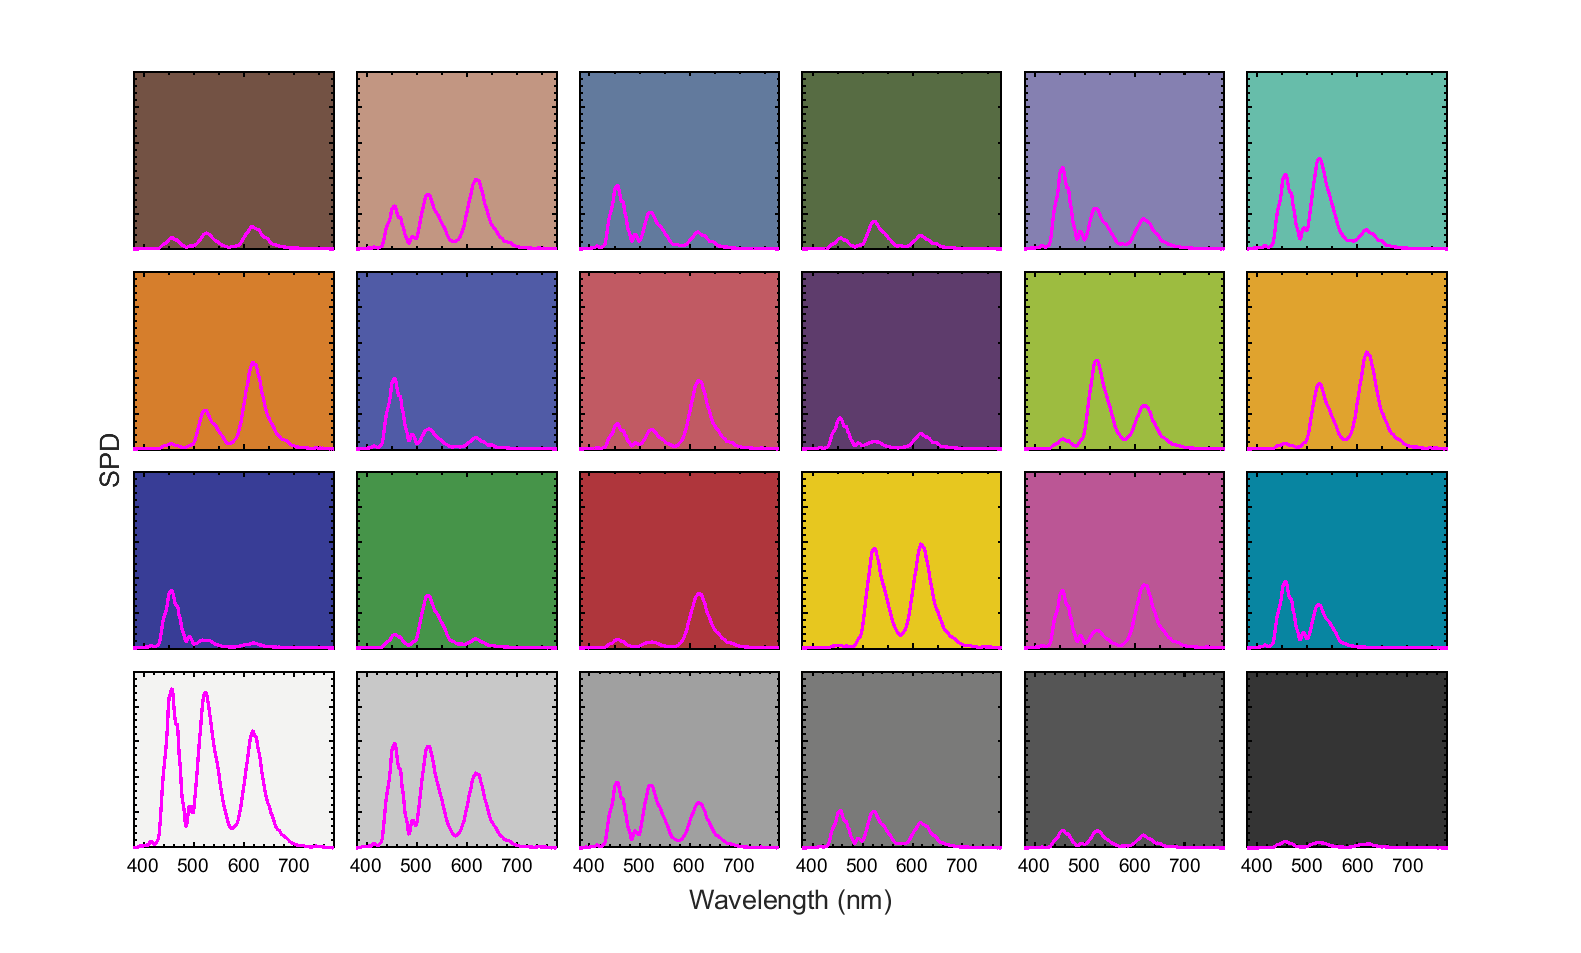

clf
td = tiledlayout(4,6,'TileSpacing','compact');
hg = gcf;
set(hg,'Visible','on');

for idx = 1:24

    haxis = nexttile(idx);
    hold on

    plot(380:780,spd_ol490_24{idx},'m-')
    axis([380 780 0 2.5e-4])

    color_rgb = [0 0.5 1];

    %    title(idx)
    yticklabels({});
    PlotBeautify(haxis)
    legend off

    % change the background color
    set(haxis,'Color',colorchecker(idx,:)/255);

    if idx < 19
        xticklabels({});
    end

    haxis.XAxis.FontSize = 14;

    yticklabels({});

    %     if mod(idx,6)==1
    %         ylabel('SPD');
    %     end

end

td.XLabel.String = 'Wavelength (nm)';
td.XLabel.FontSize = 20;

td.YLabel.String = 'SPD';
td.YLabel.FontSize = 20;

hg.Position = [97 134 1581 953];
saveas(hg,'spectra_on_colorchecker.png')

## Old

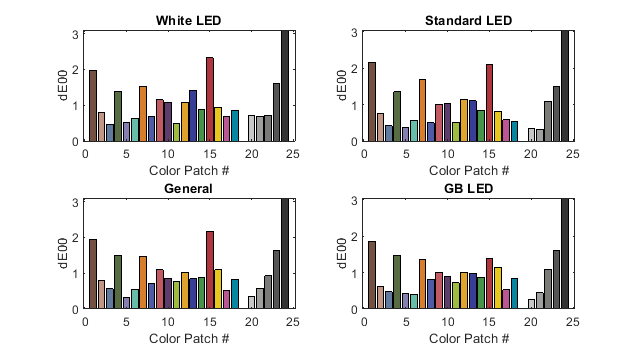


modename = {'White LED','Standard LED','General','GB LED'};

dEall = zeros(4,24);

clf
for mode = 1:4
    colstart = (mode-1)*3 + 1;

    cc = ColorConversionClass;
    load('spyder_rift','spyder')
    XYZ_cck = spyder(:,colstart:colstart+2);
    LAB_cck = cc.XYZ2lab(XYZ_cck,XYZ_cck(19,:));

    load('colorchecker_test_result_rift')
    spec = zeros(24,41);
    for i = 1:24
        s = spd_ol490_24{i};
        s = s(1:10:end);
        spec(i,:) = s;
    end

    % XYZ is 24x3
    XYZ_ol490 = cc.spd2XYZ(spec');
    LAB_ol490 = cc.XYZ2lab(XYZ_ol490,XYZ_ol490(19,:));

    for i = 1:24
        [dE00 dE94 dEab] = cc.LAB2dE(LAB_cck(i,:)',LAB_ol490(i,:)');
        dE(i) = dE00;
    end
    dEall(mode,:) = dE;

    subplot(2,2,mode)
    hbar = bar(dE,'FaceColor','flat');
    xlabel('Color Patch #')
    ylabel('dE00')
    title(modename{mode})

    for i=1:24
        hbar.CData(i,:) = colorchecker(i,:)/255;
    end
end

dEmean = mean(dEall,2);
dEstd = std(dEall,1);

saveas(gcf,'compare_dE_2x2.png')

## Compare dE among 4 modes

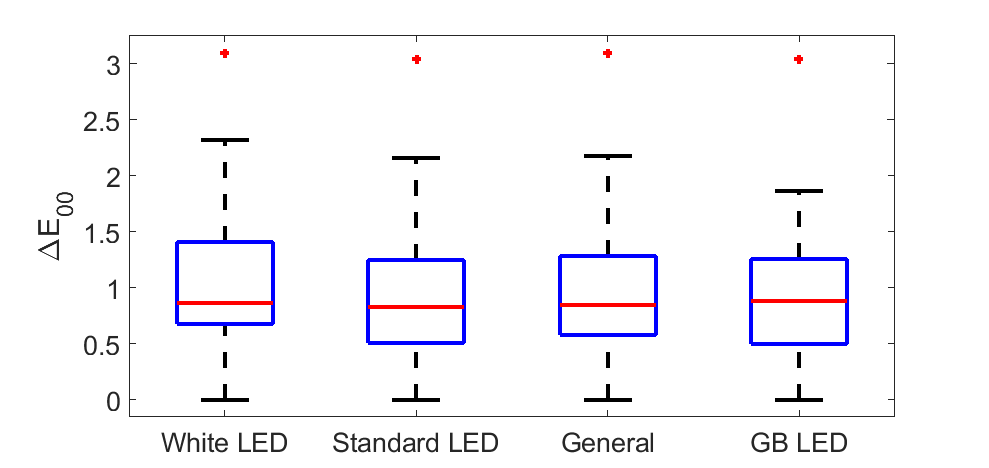

clf
hg = gcf;
set(hg,'Visible','on')
haxis = get(hg,'CurrentAxes');
boxplot(dEall','Notch','off','Labels',modename)
ylabel('\DeltaE_{00}')
set(gca,'XTickLabel',modename,'FontSize',20)

bx = findobj('Tag','boxplot');
set(bx.Children,'LineWidth',3)

saveas(gcf,'boxplot_dE.png')

## Compare dE in mode General

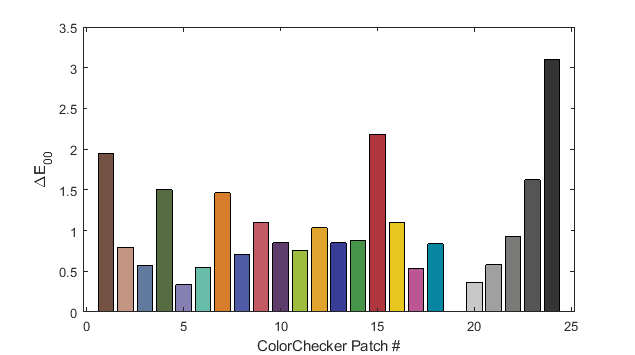

mode = 3; % general
clf
hg = gcf;
set(hg,'Visible','on');
hbar = bar(dEall(mode,:)','FaceColor','flat');
xlabel('ColorChecker Patch #')
ylabel('\DeltaE_{00}')
%title('Spyder X Accuracy')

for i=1:24
    hbar.CData(i,:) = colorchecker(i,:)/255;
end

hg.Position = [716 543 635 355];
saveas(hg,'bar_dE.png')

## Color differences of 24 patches in four different modes of Spyder X, consolidated

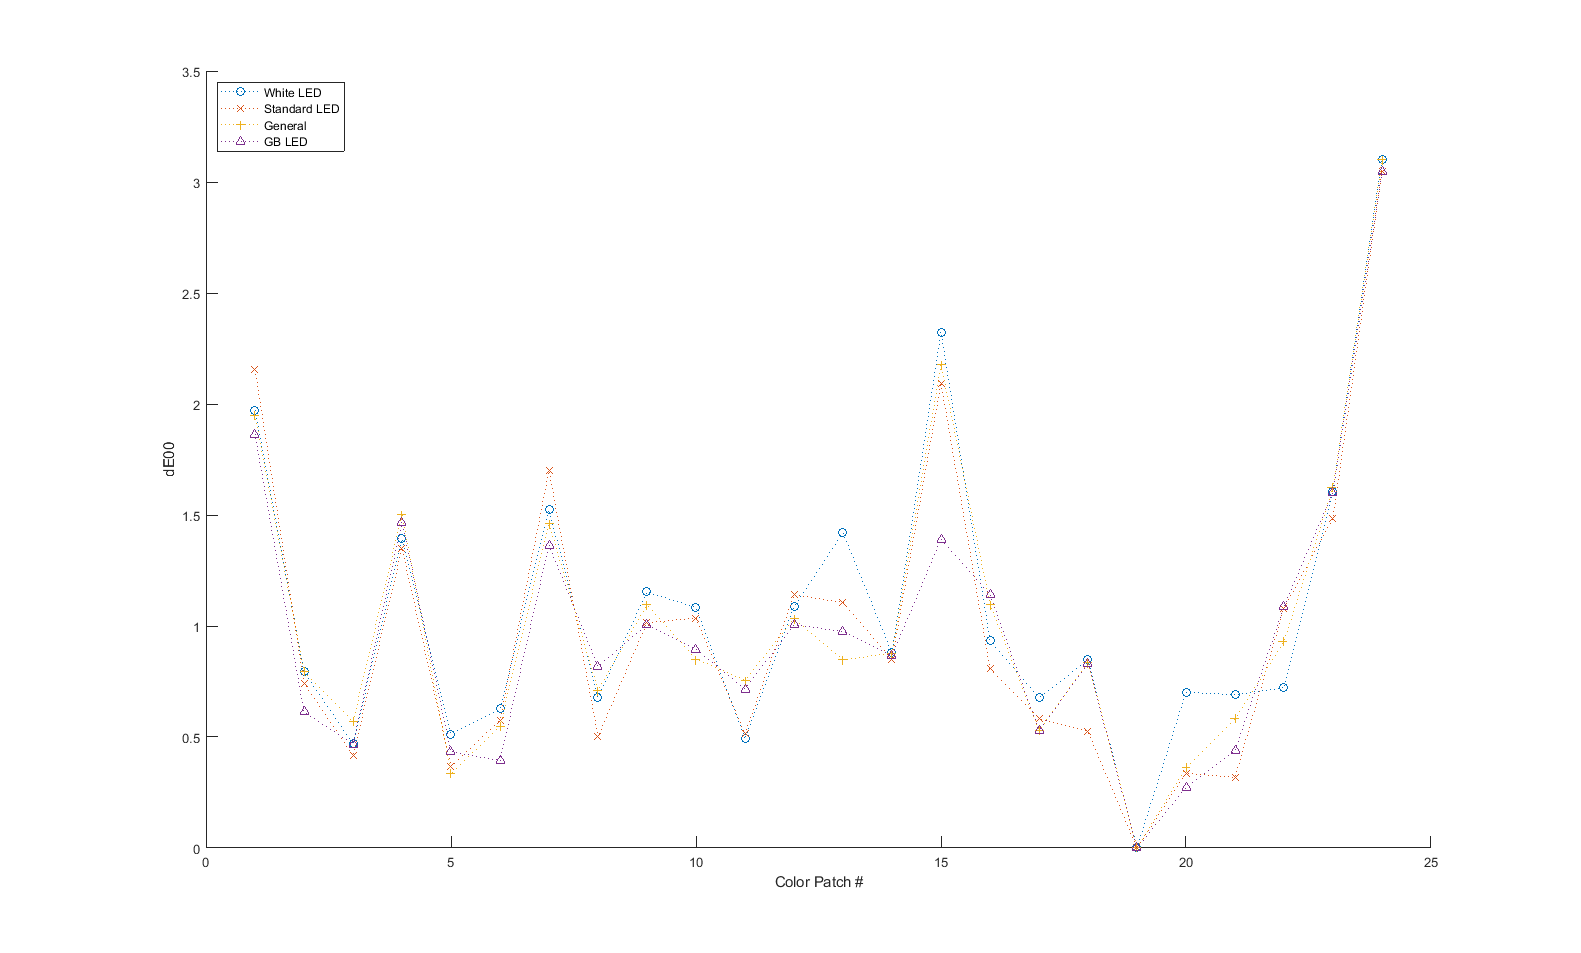

clf
hold on
plot(dEall(1,:),'o:')
plot(dEall(2,:),'x:')
plot(dEall(3,:),'+:')
plot(dEall(4,:),'^:')
xlabel('Color Patch #')
ylabel('dE00')
legend('White LED','Standard LED','General','GB LED')
legend('Location','northwest')

saveas(gcf,'compare_dE.png')

## (3D) Comparison of chromaticity in different modes (circle: reference, cross: Spyder X)

mode = 2

mode = 2

colstart = (mode-1)*3 + 1;

cc = ColorConversionClass

cc =   ColorConversionClass with properties:

           cmf: [41×4 double]
       xy_srgb: [3×2 double]
         xy_p3: [3×2 double]
    xy_rec2020: [3×2 double]


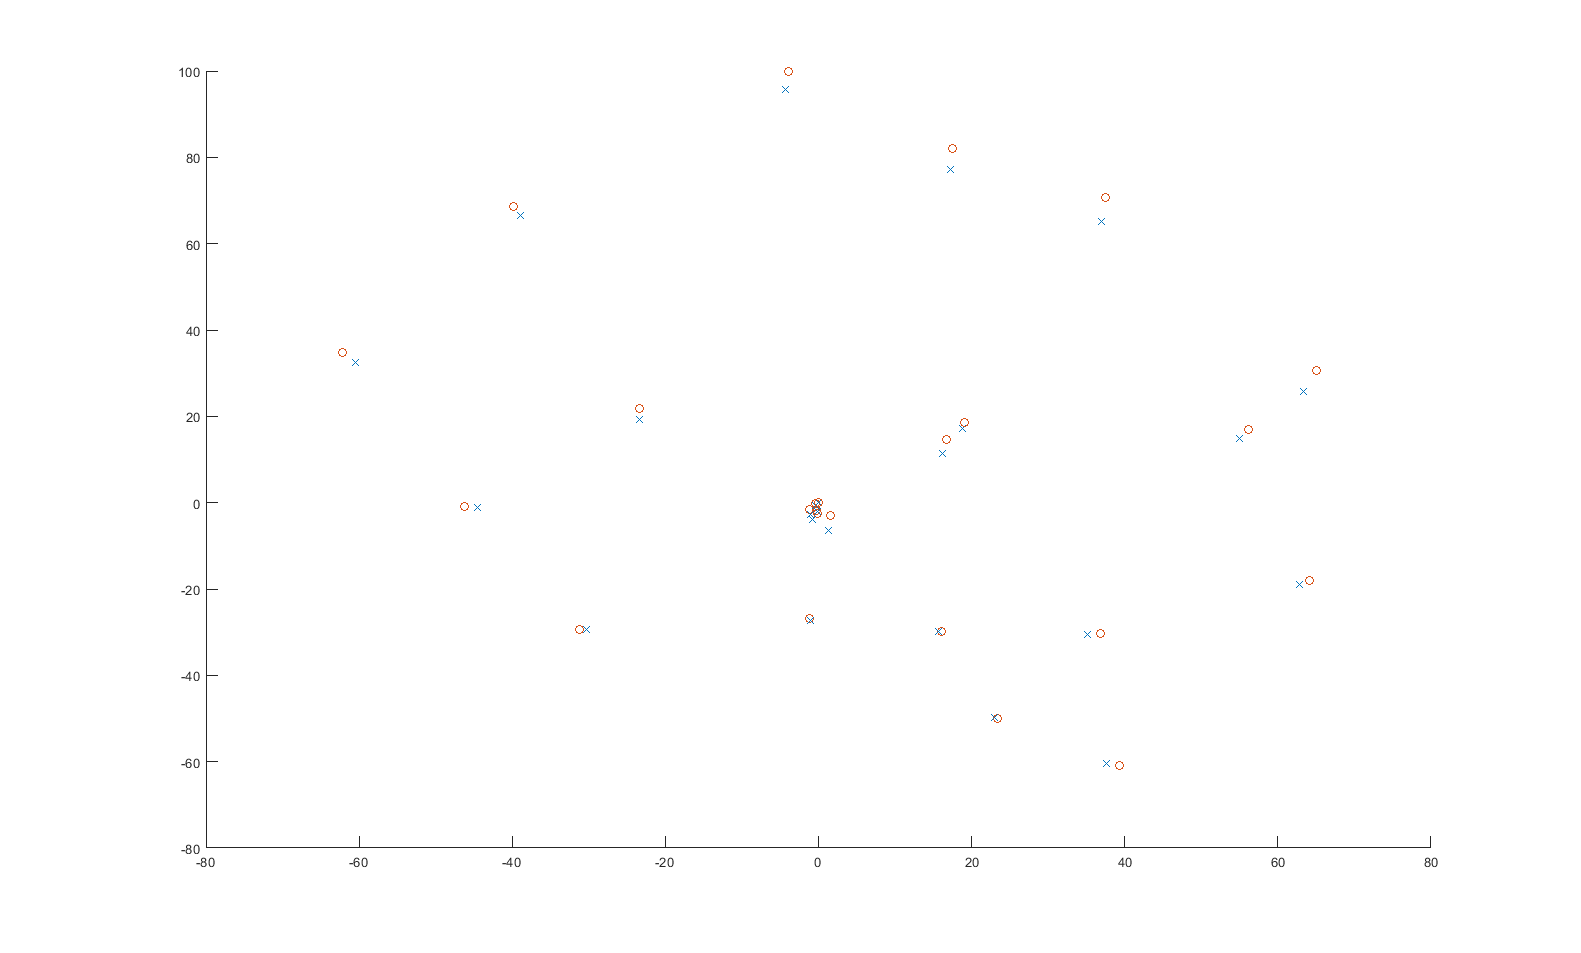

load('spyder_rift','spyder')
XYZ_cck = spyder(:,colstart:colstart+2);
LAB_cck = cc.XYZ2lab(XYZ_cck,XYZ_cck(19,:));

clf
hold on
plot3(LAB_cck(:,2),LAB_cck(:,3),LAB_cck(:,1),'x')
plot3(LAB_ol490(:,2),LAB_ol490(:,3),LAB_ol490(:,1),'o')

## Comparison of chromaticity in different modes (circle: reference, cross: Spyder X)

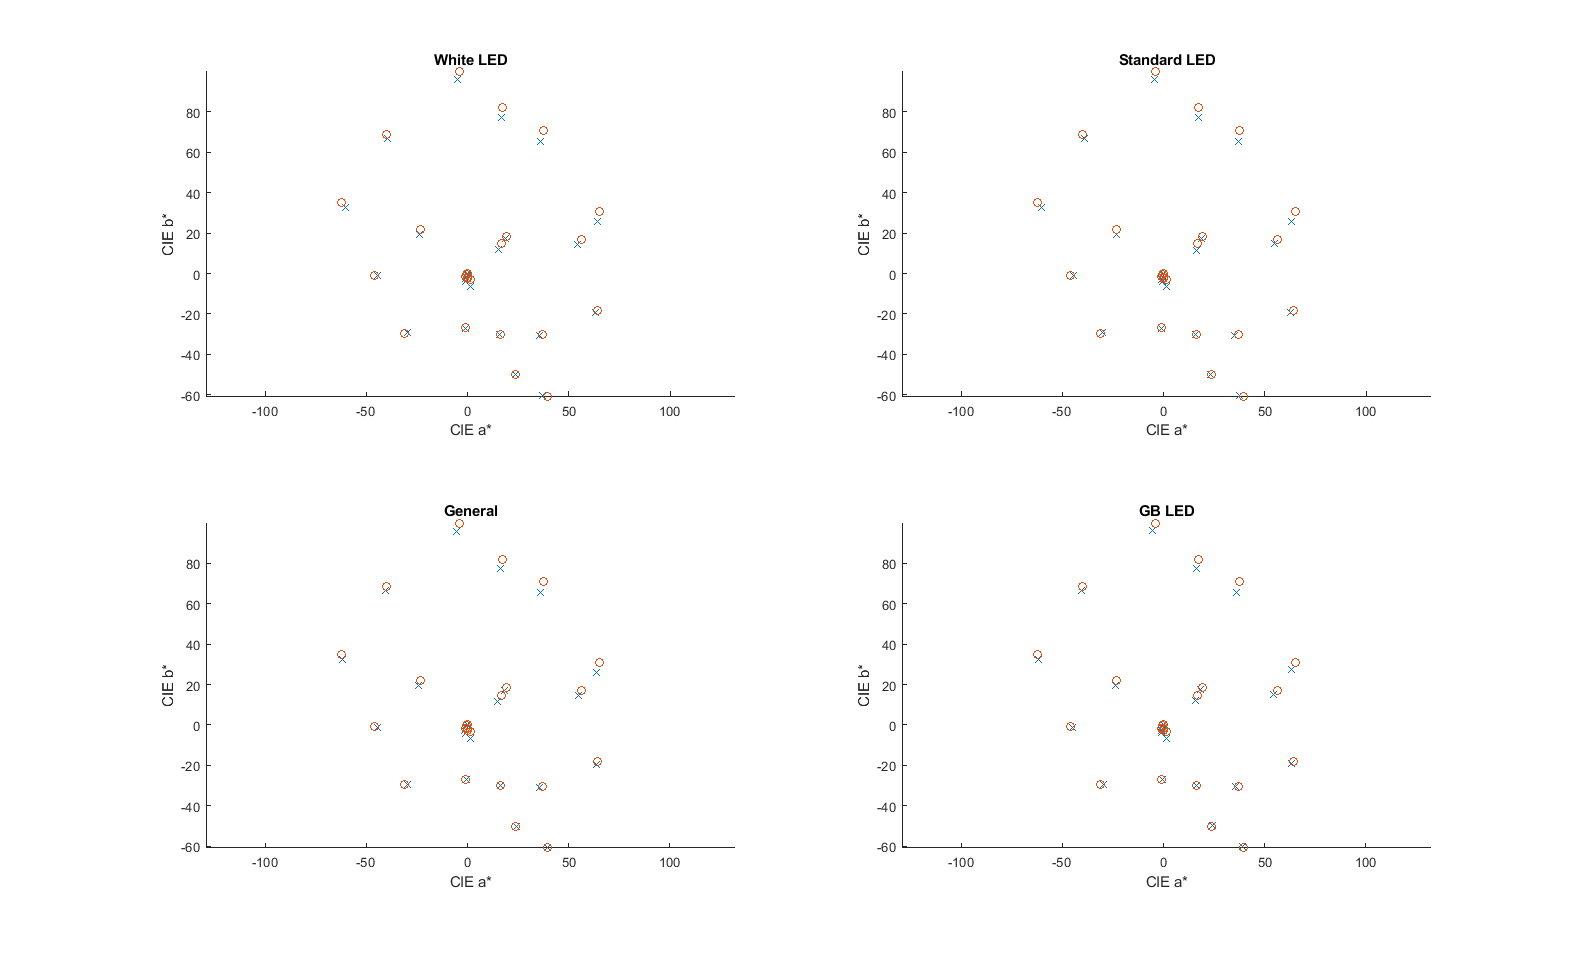

clf

for mode = 1:4
    colstart = (mode-1)*3 + 1;

    cc = ColorConversionClass;
    load('spyder_rift','spyder')
    XYZ_cck = spyder(:,colstart:colstart+2);
    LAB_cck = cc.XYZ2lab(XYZ_cck,XYZ_cck(19,:));


    subplot(2,2,mode)
    hold on
    plot(LAB_cck(:,2),LAB_cck(:,3),'x')
    plot(LAB_ol490(:,2),LAB_ol490(:,3),'o')
    xlabel('CIE a*')
    ylabel('CIE b*')
    % legend('Spyder X','Spectrometer')
    axis equal
    title(modename{mode})
end
saveas(gcf,'compare CIEab.png')

## Linearity of luminance measurements in different modes

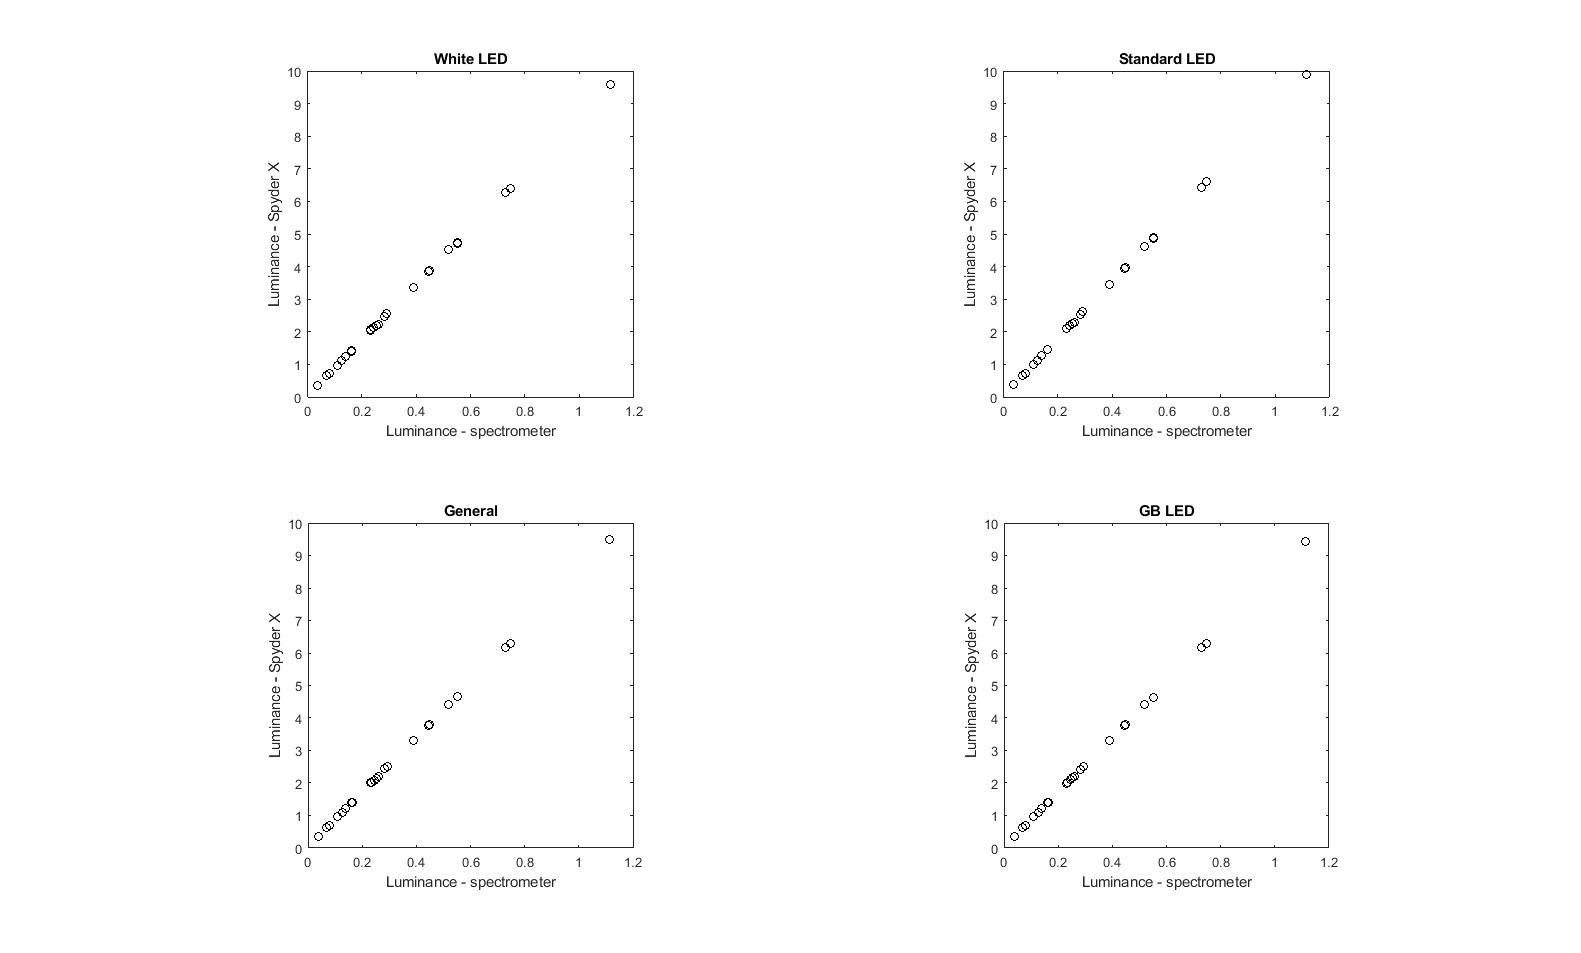

clf
hold on
symb = 'ox+^';

for mode = 1:4
    colstart = (mode-1)*3 + 1;

    cc = ColorConversionClass;
    load('spyder_rift','spyder')
    XYZ_cck = spyder(:,colstart:colstart+2);

    Y_cck = XYZ_cck(:,2);
    Y_ol490 = XYZ_ol490(:,2);

    subplot(2,2,mode)
    plot(Y_ol490*1000,Y_cck,'ok')
    xlabel('Luminance - spectrometer')
    ylabel('Luminance - Spyder X')
    title(modename{mode})
    axis square
end

saveas(gcf,'compare_luminancex4.png')

## Linearity of XYZ

clf
hold on
symb = 'ox+^';

mode = 3

mode = 3

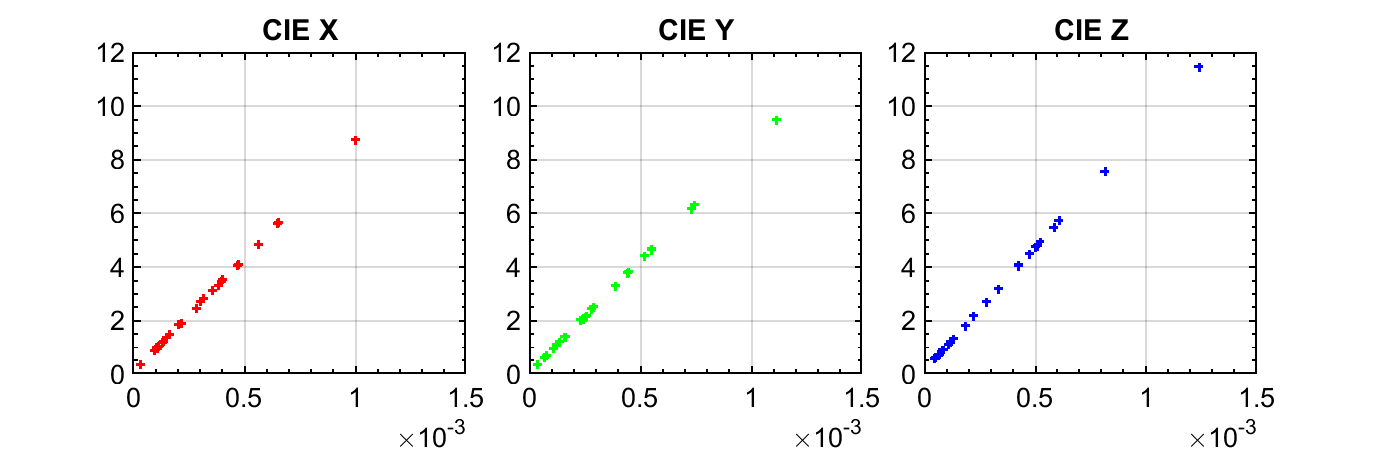

colstart = (mode-1)*3 + 1;

cc = ColorConversionClass;
load('spyder_rift','spyder')
XYZ_cck = spyder(:,colstart:colstart+2);

%
% get tristimuli
%
X_ol490_cck = [XYZ_ol490(:,1) XYZ_cck(:,1)];
Y_ol490_cck = [XYZ_ol490(:,2) XYZ_cck(:,2)];
Z_ol490_cck = [XYZ_ol490(:,3) XYZ_cck(:,3)];

%
% sort
%
X_ol490_cck = sortrows(X_ol490_cck);
Y_ol490_cck = sortrows(Y_ol490_cck);
Z_ol490_cck = sortrows(Z_ol490_cck);

%
%
%
hfig = gcf;
set(hfig,'Visible','on')

td = tiledlayout(1,3,'TileSpacing',"compact");

haxis = nexttile(1);
plot(X_ol490_cck(:,1), X_ol490_cck(:,2),'+r');
grid on
title('CIE X')
axis([0 1.5e-3 0 12])
PlotBeautify(haxis)
legend off

haxis = nexttile(2);
plot(Y_ol490_cck(:,1), Y_ol490_cck(:,2),'+g')
grid on
title('CIE Y')
axis([0 1.5e-3 0 12])
PlotBeautify(haxis)
legend off

haxis = nexttile(3);
plot(Z_ol490_cck(:,1), Z_ol490_cck(:,2),'+b')
grid on
title('CIE Z')
axis([0 1.5e-3 0 12])
PlotBeautify(haxis)
legend off

saveas(hfig,'linearity_plots.png')